# N-Back analysis of frequency data

Sam Michalka - July 2024

clear
epoch_data = readtable("NBackMLFeaturesEpoch.csv");
epoch_data.channelnames = categorical(epoch_data.channelnames);

% Split the conditions in
cond_details = split(epoch_data.type,"_");
epoch_data.time_window = categorical(cond_details(:,1));
epoch_data.numback = categorical(cond_details(:,2));
freqBands = table(["delta","theta","alpha","beta","lowerAlpha","upperAlpha","lowerBeta","upperBeta"]',...
    [1 4 8 12.5 8 10 12.5 20]', ...
    [4 8 13 30 11 13 20 30]','VariableNames',{'Names','LowFreq','HighFreq'})

freqBands = 8×3 table
       Names        LowFreq    HighFreq
    ____________    _______    ________

    "delta"             1          4   
    "theta"             4          8   
    "alpha"             8         13   
    "beta"           12.5         30   
    "lowerAlpha"        8         11   
    "upperAlpha"       10         13   
    "lowerBeta"      12.5         20   
    "upperBeta"        20         30   


## Assign clusters and analyze

load epochdataall.mat

channel_names = unique(epoch_data.channelnames)'

channel_names = 1×17 categorical array
     C3      C4      Cz      F3      F4      F7      F8      Fz      O1      O2      P3      P4      P7      P8      Pz      T7      T8 


Here is a summary of the electrodes in each cluster. You can change these if you want a different mapping of clusters.

channel_cluster = categorical({'CentroTemporal','CentroTemporal','CentroTemporal','Frontal',...
    'Frontal','Frontal','Frontal','Frontal',...
    'OccipitoParietal','OccipitoParietal','OccipitoParietal','OccipitoParietal','OccipitoParietal',...
    'OccipitoParietal','OccipitoParietal','CentroTemporal','CentroTemporal'});

channel_cluster_names = unique(channel_cluster);
for ch = 1:length(channel_cluster_names)
    disp(strcat('Channels for ', string(channel_cluster_names(ch)), ' are : '))
     channel_names(channel_cluster==channel_cluster_names(ch))
end

Channels forCentroTemporal are :


ans = 1×5 categorical array
     C3      C4      Cz      T7      T8 


Channels forFrontal are :


ans = 1×5 categorical array
     F3      F4      F7      F8      Fz 


Channels forOccipitoParietal are :


ans = 1×7 categorical array
     O1      O2      P3      P4      P7      P8      Pz 


for i = 1:height(epoch_data)
    epoch_data.chcluster(i) = channel_cluster(find(channel_names==epoch_data.channelnames(i),1));
end

The values from spectopo are

"Log Power Spectral Density 10*log_{10}(\muV^{2}/Hz)' 

We then calculate the absolute power via

 `mean``(``10``.^``(``spectra``(``deltaIdx``)``/``10``)``)``;`

`So  ``mean``(``10``.^``(`10*log_{10}(\muV^{2}/Hz)`/``10``)``)``;`

`mean(10.^(`log_{10}(\muV^{2}/Hz)`);`

`mean(`\muV^{2}/Hz))

But these results give a very skewed distribution, so I converted back to 10*log10(abspower) here:

for f = 1:length(freqBands.Names)
    eval(strcat("epoch_data.",freqBands.Names(f),"_10log10 = 10*log10(epoch_data.",freqBands.Names(f),");"));
end


## Stats

cluststattostack = grpstats(epoch_data,["chcluster","time_window","numback","id","trial"],["mean"],...
    "DataVars",["delta_10log10","theta_10log10","alpha_10log10","beta_10log10","lowerAlpha_10log10","upperAlpha_10log10","lowerBeta_10log10","upperBeta_10log10"]);

stackedClustStat = stack(cluststattostack,7:14,'NewDataVariableName','mean_10log10');

a = split(string(stackedClustStat.mean_10log10_Indicator),"_");
stackedClustStat.band = categorical(a(:,2));
stackedClustStat.mean_10log10_Indicator = []

stackedClustStat = 213384×8 table
                                        chcluster       time_window    numback      id       trial    GroupCount    mean_10log10       band   
                                      ______________    ___________    _______    _______    _____    __________    ____________    __________

    CentroTemporal_blank_1_A02_0      CentroTemporal       blank          1       {'A02'}      0          5            4.1268       delta     
    CentroTemporal_blank_1_A02_0_1    CentroTemporal       blank          1       {'A02'}      0          5           -2.2838       theta     
    CentroTemporal_blank_1_A02_0_2    CentroTemporal       blank      


bands = ["delta",...
    "theta",...
    "lowerAlpha",...
    "upperAlpha",...
    "lowerBeta",...
    "upperBeta"];
timewindow = "blank";
uncorrected_p_value_band_chclust_reg = zeros(length(bands),length(channel_cluster_names));
i = 1;
for b = 1:length(bands)
    
    for ch = 1:length(channel_cluster_names)
        temp_data = stackedClustStat(stackedClustStat.band==bands{b} & stackedClustStat.chcluster==channel_cluster_names(ch) & stackedClustStat.time_window==timewindow,:);
        %lme_tempEEG = fitlme(temp_data,'mean_logpower ~ 1 + combination + (1 + combination|id)'); % From old version using just log
        lme_tempEEG = fitlme(temp_data,'mean_10log10 ~ 1 + numback + (1 + numback|id)','FitMethod','REML');
        uncorrected_p_value_band_chclust_reg(b,ch) = lme_tempEEG.Coefficients.pValue(2); % Extract pvalues for load
        
        if i == 1
            resultsTable_EEG  = putLMEresultsTable(lme_tempEEG,"EEG");
        else
            resultsTable_EEG  = [resultsTable_EEG; putLMEresultsTable(lme_tempEEG,"EEG")];
        end

%         if lme_tempEEG.Coefficients.pValue(2) < 0.05
%             disp("Significant uncorrected")
%             disp("----------Analysis for -----------------------------------")
%             bands(b)
%             channel_cluster_names(ch)
%             lme_tempEEG
%             anova(lme_tempEEG)
%             lme_tempEEG.Rsquared
%         end
%         disp(" ")
        i = i + 1;

    end
end



If you want to do manual corrections for multiple comparison, you'll need: [https://www.mathworks.com/matlabcentral/fileexchange/28303-bonferroni-holm-correction-for-multiple-comparisons](https://www.mathworks.com/matlabcentral/fileexchange/28303-bonferroni-holm-correction-for-multiple-comparisons) or some similar function. See bonf_holm() below.

addpath('/Users/smichalka/Documents/Matlab/bonf_holm/')

First, plot the corrected and uncorrected p-values for the continuous linear mixed model (LMM).

resultsTable_EEG.correctedPvalueBH = bonf_holm(resultsTable_EEG.pValue); % need to add path after downloading toolbox (or find another)
%resultsTable_EEG.correctedPvalueFDR = fdr(resultsTable_EEG.pValue); % Need eeglab open for this.

%figure;
%imagesc(uncorrected_p_value_band_chclust_reg); clim([0 0.05]); colorbar; colormap('pink');
%xticks(1:length(channel_cluster_names)); xticklabels(channel_cluster_names);
%yticks(1:length(bands)); yticklabels(bands);
%title('Uncorrected p-values for continuous load LMM');
uncorrected_p_value_band_chclust_reg

uncorrected_p_value_band_chclust_reg =     0.1649    0.2118    0.1888
    0.0540    0.0507    0.4066
    0.4416    0.1142    0.4350
    0.4693    0.1985    0.6085
    0.1081    0.0253    0.0007
    0.0851    0.0088    0.0002


corrected_p_value_band_chclust_reg = bonf_holm(uncorrected_p_value_band_chclust_reg)

corrected_p_value_band_chclust_reg =     1.4843    1.3896    1.5107
    0.7104    0.7104    2.0332
    1.7401    1.1888    2.0332
    1.3249    1.5107    0.9387
    1.1888    0.3794    0.0121
    1.0218    0.1403    0.0042


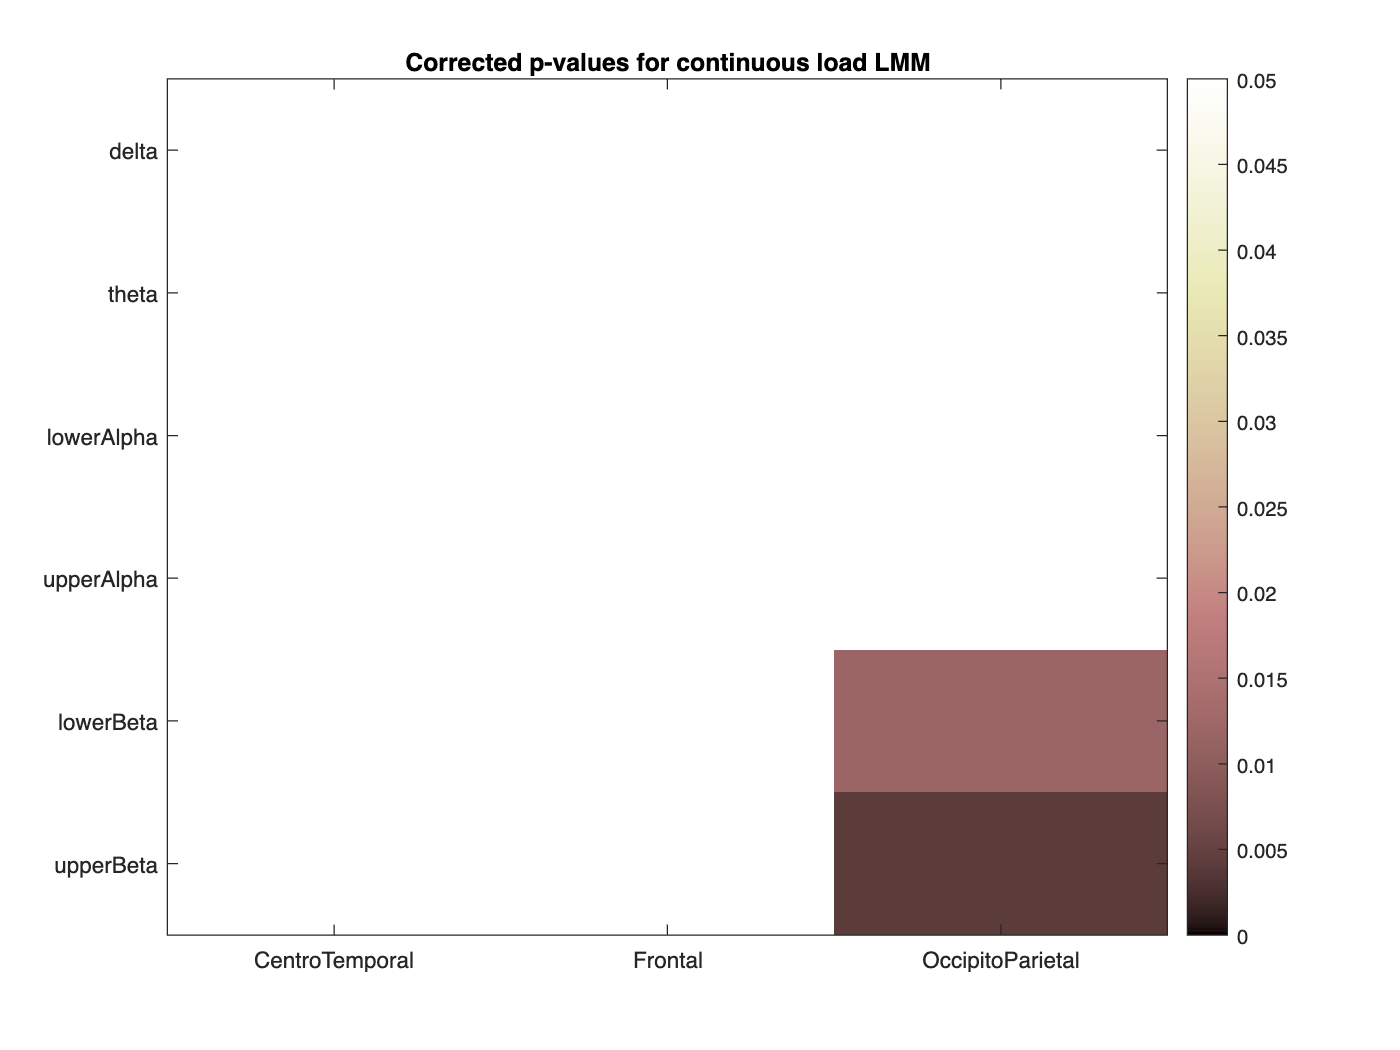

%corrected_p_value_band_chclust_reg = fdr(uncorrected_p_value_band_chclust_reg)
figure;
imagesc(corrected_p_value_band_chclust_reg); clim([0 0.05]); colorbar; colormap('pink');
xticks(1:length(channel_cluster_names)); xticklabels(channel_cluster_names);
yticks(1:length(bands)); yticklabels(bands);
title('Corrected p-values for continuous load LMM');

## Group stats

epoch_data.id = categorical(cellstr(epoch_data.id));
cluststat = grpstats(epoch_data,["chcluster","type","id"],["mean","std","sem"],...
    "DataVars",["delta_10log10","theta_10log10","alpha_10log10","beta_10log10","lowerAlpha_10log10","upperAlpha_10log10","lowerBeta_10log10","upperBeta_10log10"]);



### Plots

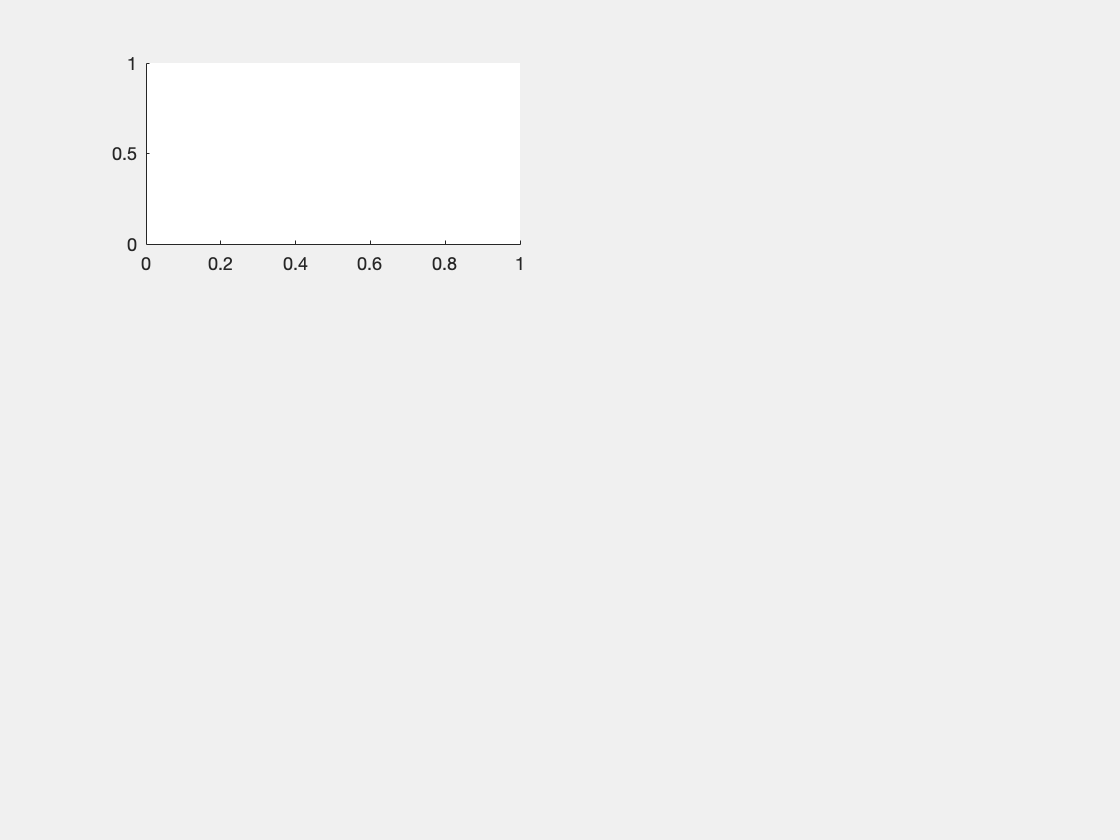

Unrecognized function or variable 'stackedClustStatMean'.


% group average
sigcorp = corrected_p_value_band_chclust_reg < 0.05;
numsig = sum(sum(sigcorp));
numSubj = length(unique(stackedClustStat.id));
CI95 = tinv([0.025 0.975], numSubj-1);
% We have to force this figure to pop out because the error bars won't be
% dashed otherwise.
figure; set(gcf,'Visible','on') 
i = 1;
for b = 1:length(bands)
    legendtext = [];
     subplot(length(bands)/2,2,b)
    for cl = 1:length(channel_cluster_names)
        subdata = stackedClustStatMean(stackedClustStatMean.band==bands{b} & stackedClustStatMean.chcluster==channel_cluster_names(cl) & stackedClustStatMean.timeWindow==timewindow,:);
        %subdata = long_EEGclust_data(long_EEGclust_data.band==bands(b) & long_EEGclust_data.channelCluster==channel_cluster_names(cl),:);
        
       
        sumstatsub = grpstats(subdata,"numLetters",["mean","sem"],"DataVars","mean_10log10","VarNames",["numLetters","GroupCount","mean","sem"]);
        
        if sigcorp(b,cl) % if sig, make plot
            lineStyle = '-';
        else
            lineStyle = ':';
        end
    
        eb = errorbar(sumstatsub.numLetters,sumstatsub.mean,CI95(2).*sumstatsub.sem,'LineStyle',lineStyle,'LineWidth',2);
        if ~sigcorp(b,cl) % if sig, make plot
            
            eb.Bar.LineStyle = 'dotted';
        end

        hold on;
                      
    end
    fontsize(gca,12,'points')
    xlim([3.75 7.25]); %xlabel('Number of Letters','FontSize',16,"FontWeight","bold");
    %ylabel({"Log Power Spectral Density", "10*log_{10}(\muV^{2}/Hz)"},'FontSize',16,"FontWeight","bold");
    title(strcat(bands{b}));

    if i ==3
        ylabel({"Log Power Spectral Density", "10*log_{10}(\muV^{2}/Hz)"},'FontSize',16,"FontWeight","bold");
    end
    if i == 5 | i==6
        xlabel("Number of Letters",'FontSize',14,"FontWeight","bold");
    end
    i = i+1;

    hold off;
end

## Helper Functions

### Calculate absolute power from the spectra for frequency bands of interest. 

function [absolutePower] = getAbsolutePower(spectra,freqs,freqBands)
% Put in a 2d spectra (ch x freqs), get out 2d matrix of ch x bandpowers
    absolutePower = zeros(size(spectra,1),height(freqBands));
    for b = 1:height(freqBands)
        % find the index of the frequencies between those values
        % (non-inclusive)
        freqIdx = find(freqs >= freqBands.LowFreq(b) & freqs<=freqBands.HighFreq(b)); % changed to include equal to because bands are on the ints
        if isempty(freqIdx)
            !warning("No frequencies fall within the range, make band larger. It is inclusive.")
        end
        % Convert spectra to mean absolute power 
        if size(size(spectra),2) == 2
            absolutePower(:,b) = mean(10.^(spectra(:,freqIdx)/10),2);
        elseif size(size(spectra),2) == 3

        else
            !warning("Too many dimensions bro")
        end
    end
end


This takes in the data with subjects as rows.

function plotAgainstConditionValues(conditionValues,tempData,metricLabel,errorBarType,individualOn)
    if individualOn
        for i = 1:size(tempData,1)
            if i <= 3
                plot(conditionValues,tempData(i,:),'x-','MarkerSize',10);
                hold on;  
            elseif i <=10
                plot(conditionValues,tempData(i,:),'d--','MarkerSize',8);
                hold on;  
            else
                plot(conditionValues,tempData(i,:),'o-.','MarkerSize',10);
                hold on;
            end
                
        end
    end
    errorVals = calculateError(tempData,errorBarType);
    errorbar(conditionValues,mean(tempData),errorVals,'k','LineWidth',2);
    plot(conditionValues,mean(tempData),'k.','MarkerSize',30); 
    hold off;
    fontsize(gca,12,'points')
    xlim([3.75 7.25]); xticks(4:7); xlabel('Number of Letters','FontSize',16,"FontWeight","bold");
    ylabel(metricLabel,'FontSize',16,"FontWeight","bold");

end
function [errorValues ] = calculateError(dataSubjsAsRows,errorType)
    numSubj = size(dataSubjsAsRows,1);    
    switch errorType
        case 'std'
            errorValues = std(dataSubjsAsRows);
        case 'sem'
            errorValues = std(dataSubjsAsRows)./sqrt(numSubj);
        case '95sem'
            CI95 = tinv([0.025 0.975], numSubj-1);
            errorValues = CI95(2).*(std(dataSubjsAsRows)./sqrt(numSubj));
        otherwise
            warning('errorType does not match any options, returning zeros')
            errorValues = zeros(1,size(dataSubjsAsRows,2));
    end  
end

function [outtable] = putLMEresultsTable(lmemodel,sourceType)

    [~,~,stats] = covarianceParameters(lmemodel);
    if sourceType == "EEG"
        outtable = table(lmemodel.Variables.band(1),...
            lmemodel.Variables.chcluster(1),... 
            lmemodel.Coefficients(2,:).Estimate,...
            lmemodel.Coefficients(2,:).SE,...
            lmemodel.Coefficients(2,:).tStat,...
            lmemodel.Coefficients(2,:).pValue,...
            lmemodel.Coefficients(2,:).Lower,...
            lmemodel.Coefficients(2,:).Upper,...
            lmemodel.ModelCriterion.AIC,...
            lmemodel.ModelCriterion.LogLikelihood,...
            lmemodel.Rsquared.Adjusted,...
            stats{1}(3,5).Estimate,...
            'VariableNames',{'chcluster','Band','Estimate','SE','tStat','pValue','Lower','Upper','AIC','LL','AdjRsquared','RandomEffectsStd'});
    else
        loadValIdx = find(strcmp(lmemodel.CoefficientNames,'LoadVal'));
        outtable = table(sourceType,... 
            lmemodel.Coefficients(loadValIdx,:).Estimate,...
            lmemodel.Coefficients(loadValIdx,:).SE,...
            lmemodel.Coefficients(loadValIdx,:).tStat,...
            lmemodel.Coefficients(loadValIdx,:).DF,...
            lmemodel.Coefficients(loadValIdx,:).pValue,...
            lmemodel.Coefficients(loadValIdx,:).Lower,...
            lmemodel.Coefficients(loadValIdx,:).Upper,...
            lmemodel.ModelCriterion.AIC,...
            lmemodel.ModelCriterion.LogLikelihood,...
            lmemodel.Rsquared.Adjusted,...
            stats{1}(3,5).Estimate,...
            'VariableNames',{'Measurement','Estimate','SE','tStat','df','pValue','Lower','Upper','AIC','LL','AdjRsquared','RandomEffectsStd'});

    end
end